close all;
clear variables;
clc;

## Read the training, validation and test partitions from the relevant

folder = "CUB_200_2011_Subset20classes";
trainingImageNames = readtable(fullfile(folder, "train.txt"),'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(fullfile(folder, "validate.txt"),'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(fullfile(folder, "test.txt"),'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(fullfile(folder, "classes.txt"),'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(fullfile(folder, "image_class_labels.txt"),'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

folder = "CUB_200_2011_Subset20classes/";
trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;

validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;

testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;

## The images all have different spatial resolutions (width x height), so

targetSize = [224, 224];
trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);
labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);
labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

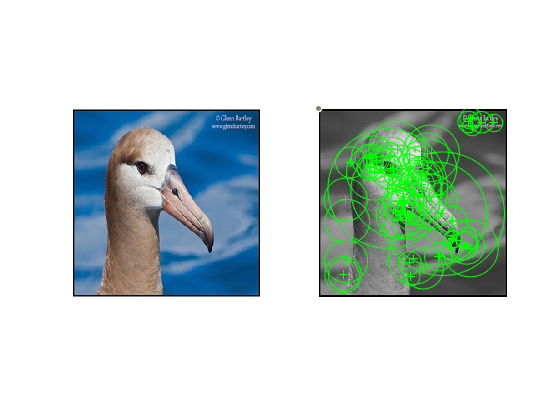

% select the first image
img = cdsTraining.read{1};
surfPoints = detectSURFFeatures(rgb2gray(img));
subplot(1, 2, 1);
imshow(img);
subplot(1, 2, 2);
imshow(rgb2gray(img)); hold on;
plot(surfPoints);
hold off;

%surf
dataset_size = 1;
trainingFeatures = zeros(dataset_size, 2000, 'single');
reset(cdsTraining);     % Make sure we start with the first image
for i = 1:dataset_size
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.
    imgGray = im2gray(imgFromDS{1});      % Ensure images are grayscale 
    points = detectSURFFeatures(imgGray);  
    features = extractFeatures(imgGray, points);
    sz = size(features);
    trainingFeatures(i, 1:sz(1)*sz(2)) = reshape(features, 1, []);
end

% surf test

numImagesTest = numel(testImageDS_Resized.UnderlyingDatastores{1, 1}.Files);

testFeatures = zeros(numImagesTest, 2200, 'single');
reset(cdsTraining);     % Make sure we start with the first image
for i = 1:numImagesTest
    imgFromDS = read(cdsTraining);    % Get item from datastore. Note, this returns a cell array.
    imgGray = im2gray(imgFromDS{1});      % Ensure images are grayscale 
    points = detectSURFFeatures(imgGray);  
    features = extractFeatures(imgGray, points);
    sz = size(features);
    testFeatures(i, 1:sz(1)*sz(2)) = reshape(features, 1, []);
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 2).
Copying objective function to workers...
Done copying objective function to workers.
|================================================================================================|
| Iter | Active  | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Lambda |
|      | workers | result |             | runtime     | (observed)  | (estim.)    |              |
|================================================================================================|
|    1 |       1 | Best   |     0.92943 |      157.41 |     0.92943 |     0.92943 |      0.01277 |
|    2 |       1 | Accept |     0.92943 |      157.22 |     0.92943 |     0.92943 |   2.8381e-08 |
|    3 |       2 | Accept |     0.93544 |      221.84 |     0.92943 |     0.93142 |   1.6538e-05 |
|    4 |       2 | Best   |     0.92793 |      221.15 |     0.92793 |     0.93056 |   0.00038413 |
|

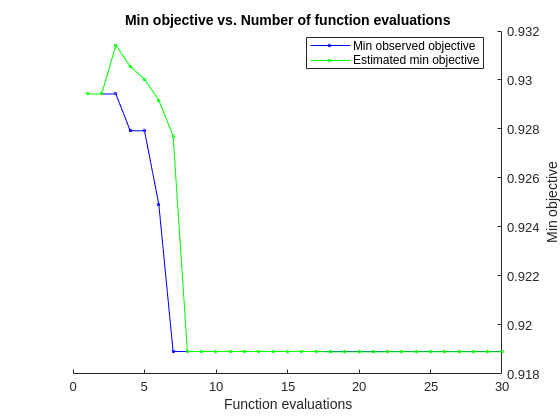

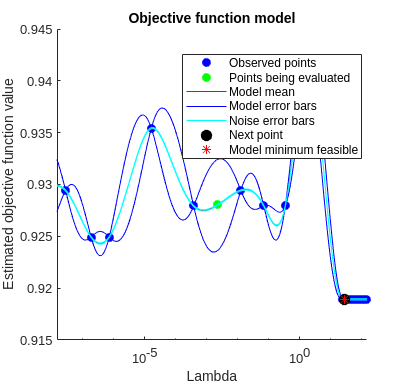


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 2207.7755 seconds
Total objective function evaluation time: 4284.4982

Best observed feasible point:
    Lambda
    ______

    150.06

Observed objective function value = 0.91892
Estimated objective function value = 0.91892
Function evaluation time = 117.9427

Best estimated feasible point (according to models):
    Lambda
    ______

    28.808

Estimated objective function value = 0.91891
Estimated function evaluation time = 136.2616



t = templateLinear('Solver', 'dual');
options = struct('UseParallel', true);
% using one vs one classifier for now
% sift has better accuracy with this ATM
Classifier = fitcecoc(trainingFeatures, trainingImageDS.Labels, 'Learners', t,...
    'OptimizeHyperparameters', {'Lambda'}, ...
    'HyperparameterOptimizationOptions', options);

## Test the accuracy on the test partition

YPred = predict(Classifier, testFeatures);
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.0541

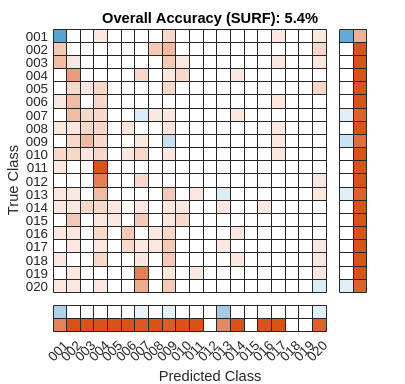


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (SURF): "+ string(round(accuracy*100, 1)) +"%");